# Primeira Prova - 25/09

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

clear all;        % Limpa as variáveis
clc;              % limpa a tela
close all;        % limpa os gráficos

**Questão 1**

% Definindo ganho de malha aberta com Kp = 1
Kp_1=1;
num1=[0 1 1];
denMa=[1 4 -32];
Gma_1=tf(num1*Kp_1,denMa)

Gma_1 =
 
      s + 1
  --------------
  s^2 + 4 s - 32
 
Continuous-time transfer function.





denMf = denMa+num1*Kp_1;
Gmf_1 = tf(num1*Kp_1,denMf)

Gmf_1 =
 
      s + 1
  --------------
  s^2 + 5 s - 31
 
Continuous-time transfer function.



% step(Gmf_1)
% Sistema eh instavel. Simulink mostra como esta comparacao
% Apos calculos, descobri que Kp deve ser maior que 32 para o sistema ser
% estavel

**Questão 2**

Regras que devem ser seguidas para achar Kp:

O erro estacionario ao degrau deve ser nulo

O erro estacionario quando a entrada R(s) for uma rampa deve ser inferior a 10%

O amortecimento deve ser: ζ > 0.707

O sobressinal deve ser: Mp< 20%


Kp_2=1; % Chute inicial para Kp
s = tf('s');
Gma_2=tf(4,[1 4 0]);
Gmf_2 = tf(4*Kp_2,[1 4 4*Kp_2])

Gmf_2 =
 
        4
  -------------
  s^2 + 4 s + 4
 
Continuous-time transfer function.




num_mf = cell2mat(Gmf_2.Numerator);
den_mf = cell2mat(Gmf_2.Denominator);
raizes = roots(den_mf)

raizes =     -2
    -2


Usando sisotool(Gmf_2), podemos ver que a parte imaginaria varia em [-2,2] - esse valor vem das limitações impostas pelo amortecimento e o sobressinal . Com isso, vemos que por Baskhara, -16<16-16 Kp<0.

Com isso, chegamos em Kp = [1,2]

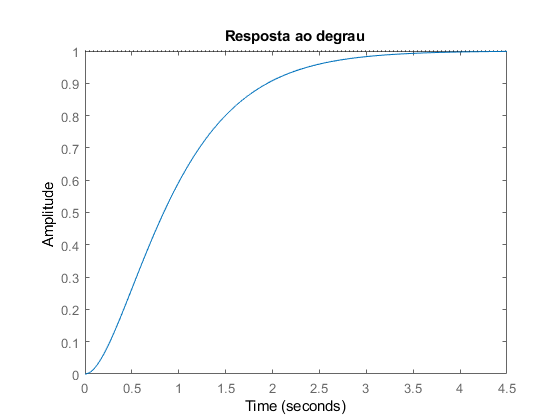

figure
step(Gmf_2)
title("Resposta ao degrau");



figure
step(Gmf_2/s)
hold;

Current plot held


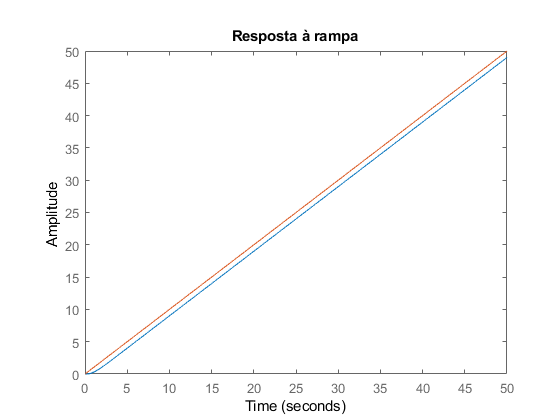

step(1/s)
title("Resposta à rampa");

**Questão 3**

**Questão 4**

No gráfico da figura 2 temos a resposta ao degrau unitário de um sistema de segunda ordem operando em malha fechada, com realimentação unitária. Determine com base na análise temporal a função de transferência de malha fechada. É possível estimar a função de transferência de malha aberta? se sim qual seria?

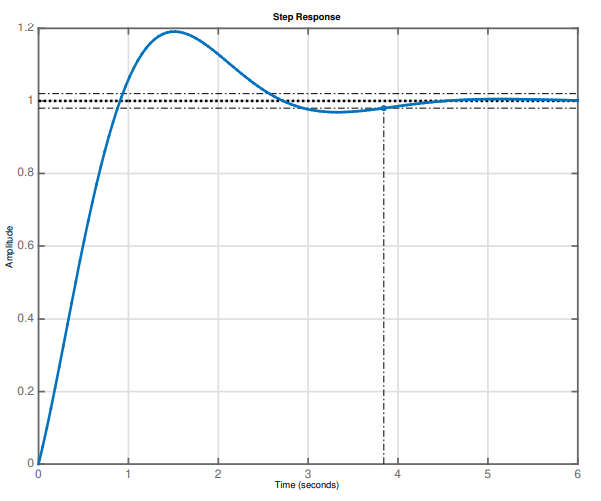

Afirmações:

Se $\mathrm{Gmf}=\frac{\mathrm{Gma}}{1+\mathrm{Gma}}$, então $\mathrm{Gma}=\frac{\mathrm{Gmf}}{1-\mathrm{Gmf}}$

No gráfico, $\mathrm{Mp}\left(%\right)\approx 20$, $\mathrm{Ts}\left(2%\right)\approx 3,8\;s$ 

Mp = 0.18;
Ts = 4;
zeta = sqrt((log(Mp)^2)/(pi^2+(log(Mp)^2)));
wn = 4/(Ts*zeta)

wn = 2.0872

Usando a segunda forma canônica:


$$\mathrm{Gmf}=\frac{{w_n }^2 }{s^2 +2\zeta w_n s+{w_n }^2 }$$


- chegamos em:

Gmf_4 = tf(wn^2,[1 2*zeta*wn wn^2])

Gmf_4 =
 
        4.356
  -----------------
  s^2 + 2 s + 4.356
 
Continuous-time transfer function.



figure
informacoes = stepinfo(Gmf_4)
step(Gmf_4)


informacoes = struct with fields:
        RiseTime: 0.7662
    SettlingTime: 3.9423
     SettlingMin: 0.9120
     SettlingMax: 1.1800
       Overshoot: 17.9953
      Undershoot: 0
            Peak: 1.1800
        PeakTime: 1.7039


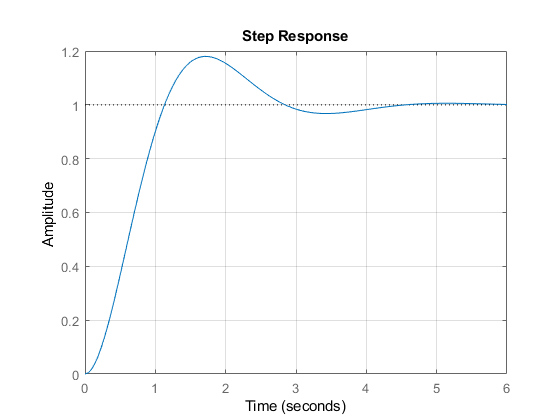

ans = 3.9423

grid;